## **Lead-Lag and Inverse Response Systems**

### **Learning Objectives: To be able to... **

**1) Be able to explain the key parameters of lead lag and time delay systems by articulating how changes in these parameters affect their dynamic behavior**

**2) Be able to utilize mathematics and simulation to assess dynamic behavior of lead lag and inverse response systems under different forcing functions**

A lead-lag system has the following transfer function: $g(s) = K\frac{(\xi s + 1)}{(\tau s + 1)}$, where $K$ is the system gain; $\xi$ is the lead time constant; and $\tau$ is the lag time constant. We define $\rho = \frac{\xi}{\tau}$ is known as the lead-to-lag ratio. By analysis, we see that the system has one pole at $s = \frac{-1}{\tau}$ and one zero at $s=\frac{-1}{\xi}$. Chemical processes typically are not lead-lag systems; however, the introduction of controllers can result in lead-lag system type behaviors. Note that the transfer function resembles that of a first order system, with an additional $\xi s+1$ term in the numerator. 

The output response for the system is given as: $y(s) = [\rho K + (1-\rho)(\frac{K}{\tau s + 1})]u(s)$, which can be seen as an average of a pure gain system and a first order system, weighted by $\rho$, the lead-to-lag ratio. 

**Question 1:** Keeping $K$ constant, what happens when you adjust $\tau$? What happens when you adjust $\xi$? What does this correspond to physically? 

**Question 2**: Set $\tau = \xi$. What response do you see? 

**Question 3**: Set $\tau < \xi$. What response do you see?

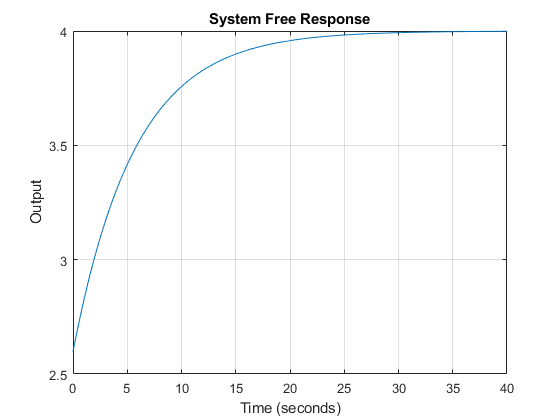


%Lead Lag Systems

k = 4;
Tau =5.7;
xi =3.7;
EndTime = 40;
[A B C D] = tf2ss([k*xi k],[Tau 1]); x0 = 0;
sys = ss(A,B,C,D);
t = 0:0.01:EndTime; 
[~,z] = size(t);
u = ones(1,z)*1;
[y] = lsim(sys,u,t,x0);
figure(1);
plot(t,y);
grid
xlabel('Time (seconds)')
ylabel('Output')
title('System Free Response')

## Inverse Response Systems

An inverse response is when the initial direction of a process reponse is the opposite direction of the final steady state value. We see that the inverse reponse is associated with a  positive zero (RHP).  Consider the following system governed by two processes, a "Main" and an "Opposition" process. Given by $g_1(s) = \frac{K_1}{\tau_1 s + 1}$ and $g_2(s) = \frac{K_2}{\tau_2 s + 1}$ parameterized by process gains $K_1$,  $K_2$ and time constants $\tau_1$, $\tau_2$, respectively.

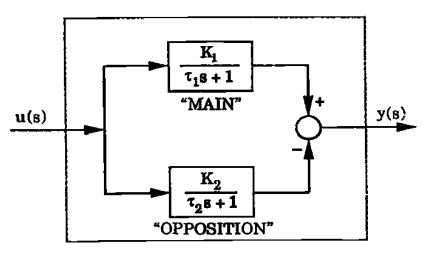

The overall transfer function of this model is given by 

$g(s) = ( \frac{K_1}{\tau_1 s + 1} - \frac{K_2}{\tau_2 s + 1}$) = $\frac{(K_1\tau_2 - K_2\tau_1)s + (K_1 - K_2)}{(\tau_1 s + 1)(\tau_2 s + 1)$ = $\frac{K(\xi s + 1)}{(\tau_1 s + 1)(\tau_2 s + 1)$, where

$K = K_1 - K_2$ and $\xi = \frac{K_1\tau_2 - K_2\tau_1}{K_1-K_2}$,

Question 1: What determines the final steady state value for this system? 

Question 2: When will this system exihibit first order behavior? 

Question 3: Keeping $K_1$, $K_2$, and $\tau_1$ the same, vary $\tau_2$. When does the system display inverse response behavior? When does the system display overshoot? 

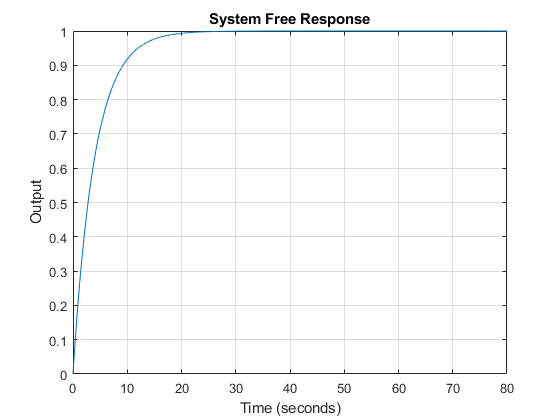

K1 = 6;
K2 = 5;
Tau1 = 4;
Tau2 = 4;   

K = K1-K2;
Xi = (K1*Tau2 - K2*Tau1)/K;

EndTime = 80;
[A B C D] = tf2ss([K*Xi K],[Tau1*Tau2 Tau1+Tau2 1 ]); x0 = [0 0];
sys = ss(A,B,C,D);
t = 0:0.01:EndTime; 
[~,z] = size(t);
u = ones(1,z)*1;
[y] = lsim(sys,u,t,x0);
figure(1);
plot(t,y);
grid
xlabel('Time (seconds)')
ylabel('Output')
title('System Free Response')